# MATLAB Exponential Script Sandbox

Here, we are calculating exponential growth.  

This is where someing increases (or alternatively decresses; that's "exponential decay")

This is a common mathematical relationship that ties to physical and biological systems.

Examples include radioactive decay, growth of icky things (and populations in general), and the slow decay of a population (the more people you have, the more you lose to old age just by playing the numbers).

We calculate a change on a population or other quantity by multiplying the current number of "stuff" by a growth or decay rate.

The basic formula for this is


$$\frac{\text{d}}{\text{d}t}x=a\text{ }x$$


With a little Calc-Fu (or Diff-E-Fu)...


$$\begin{array}{l}
\frac{\text{d}}{\text{d}t}x=a\text{ }x\\
\mathit{dx}=a\text{ }x\text{ }\mathit{dt}\\
\int_{x_0 }^{x\left(t\right)} \frac{1}{x}\mathit{dx}=a\int_0^t \text{ }\mathit{dt}\\
\mathrm{ln}\left(\frac{x\left(t\right)}{x_0 }\right)=a\text{ }t\\
\frac{x\left(t\right)}{x_0 }=e^{a\text{ }t} \\
x\left(t\right)=x_0 \text{ }e^{a\text{ }t} 
\end{array}$$


When we model, we often use a time-increment approach.  Here we are using a simple approach called Euler's Method (it's also called a First-Order Runge Kutta Method).  

In this case we strip down a Taylor series to include only the Zero and First order Terms.


$$\begin{array}{l}
x\left(t+\Delta t\right)=x\left(t\right)+\left\lbrack \frac{\mathrm{d}}{\mathrm{d}t}x\left(t\right)\right\rbrack \Delta t+\frac{1}{2!}\left\lbrack \frac{{\textrm{d}}^2 }{\textrm{d}t^2 }x\left(t\right)\right\rbrack \Delta t+\frac{1}{3!}\left\lbrack \frac{{\textrm{d}}^3 }{\textrm{d}t^3 }x\left(t\right)\right\rbrack \Delta t\ldotp \ldotp \ldotp \\
x\left(t+\Delta t\right)\approx x\left(t\right)+\left\lbrack \frac{\mathrm{d}}{\mathrm{d}t}x\left(t\right)\right\rbrack \Delta t\\
x\left(t+\Delta t\right)\approx x\left(t\right)+\left\lbrack a\;x\left(t\right)\right\rbrack \Delta t
\end{array}$$


The smaller the increment the closer you get to the true solution but the more "expensive" it is from the computational expense (and time) perspective.

x0  = 1.0;   % starting value of x
a   = 2.0;   % growth rate of x per unit time

t0  = 0.00;   % starting time
tf  = 4.00;   % ending time
dt  = 0.05;   % time increment

t  = t0:dt:tf;   % time array
nt = numel(t);   % the function that gives you the size of an array


x    = t .* 0.0; % lazy/smart way to create x
x(1) = x0;       % and now we put our initial condition in x

for m = 2 : nt                   % let's loop from our first new time step 2, to the end.
    dxdt = a*x(m-1);             % here's our rate of change…
    x(m) = x(m-1) + dxdt .* dt;  % and here we march one step forward in time!
end

true_x = x0 * exp(a .* t); % this is the analytic (true) solution to x


We can also show you how to customize plot colors and symbols.  Guidance can be found here as well as in your Matlab primer on D2L.

[https://www.mathworks.com/help/matlab/ref/linespec.html](https://www.mathworks.com/help/matlab/ref/linespec.html)

To do the fancy superscripts, subscripts and greek letters... here is a primer.

[https://www.mathworks.com/help/matlab/creating_plots/greek-letters-and-special-characters-in-graph-text.html](https://www.mathworks.com/help/matlab/creating_plots/greek-letters-and-special-characters-in-graph-text.html) 

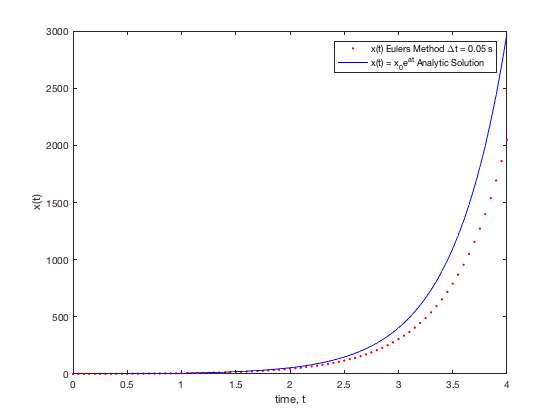

plot(  t, x,       'r.', ...    % too much for one line?   Use three dots to continue ...
       t, true_x, '-b')         % on the next line
    legend('x(t) Eulers Method \Deltat = 0.05 s', ...
           'x(t) = x_{0}e^{at} Analytic Solution'    ); % add a legend...
    xlabel('time, t');                    % add an x-label
    ylabel('x(t)');                       % add a y-label

As you can see the the error in our modeled values (red) slowly diverges from our "true" analytic solution (blue).   

Let's try this again with a smaller time step...

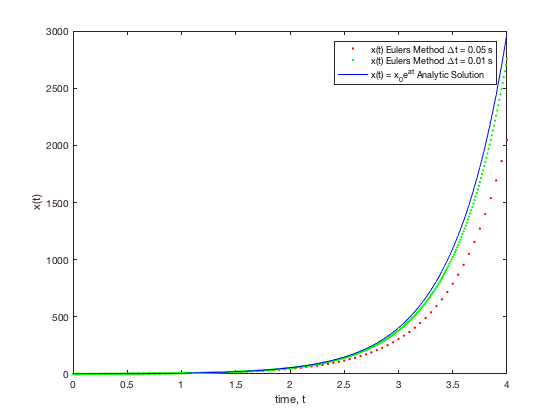

dt  = 0.01;         % here we need to create a new delta_t

t2    = t0:dt:tf;   % ... and a new time array... 
x2    = t2 .* 0.0;  % ... and a new x array...
nt2    = numel(t2); % ... and new total number of elements (i.e, cost)

% otherwise it's the same as before...

x2(1) = x0;       

for m = 2 : nt2                   
    dxdt  = a*x2(m-1);             
    x2(m) = x2(m-1) + dxdt .* dt; 
end

plot(  t,      x, 'r.', ...    
       t2,    x2, 'g.', ...
       t, true_x, '-b')        
    legend('x(t) Eulers Method \Deltat = 0.05 s', ...
           'x(t) Eulers Method \Deltat = 0.01 s',...
           'x(t) = x_{0}e^{at} Analytic Solution'    ); 
    xlabel('time, t');                  
    ylabel('x(t)');                      

So our higher temporal resolution simiulation has more accuracty but is less efficient (it will take longer to compute).  

A major challenge of modeling is to be as accurate we can be, but still be able to complete our simiulations in time to acutally use the output for decision making.  To do this we often use higher order approaches such as higher-order Runge-Kuttta methods that emulate including more of the Taylor Series.  But that's for when you are in Differential Equations...  We have a set of figures to show how these Runge-Kutta methods from a course lecture [here](https://github.com/wjcapehart/SDMines_CEE_AES_Math_Ed_Resources/blob/master/Eulers_and_Runge_Kutta_Method/Mathcad_Prime/2015_L04_RUNGE-KUTTA.Full_Screen_Slides.pdf).